# Forward Modeling of Single-sided Magnetic Resonance Based on Geometric Analytical Method

Data : 24.03.05

Author: Ruixin Miao

Fucntion :  Comparison of Geometric Analysis Method(GAM), Rotation Matrix Method(RM), and 4-5th Order Runge Kutta Method(RK45)

## 2. Magnetization vector(Single Larmor Frequency + on-resonance)

ni = 1;
gamma = 0.267518*1e9;        % Magnetic spin ratio
forwarding.B0.Hsum = 1e-2;
forwarding.TLoop.fT = gamma/2/pi*forwarding.B0.Hsum;
B1 = 1e-3;
T = [0:1e-8:5e-5]';
[M0_G] = IntegralM0_GM(forwarding,B1,ni,T);
[M0_RM] = IntegralM0_RM(forwarding,B1,ni,T);
Lt = length(T);
xxx = abs(M0_G.rx - M0_RM.rx)./abs(M0_RM.rx);
xxx(isnan(xxx)) = 0;
yyy = abs(M0_G.ry - M0_RM.ry)./abs(M0_RM.ry);
yyy(isnan(yyy)) = 0;
zzz = abs(M0_G.rz - M0_RM.rz)./abs(M0_RM.rz);
zzz(isnan(zzz)) = 0;
MAPE_X = mean(xxx,"all")*100
MAPE_Y = mean(yyy,"all")*100
MAPE_Z = mean(zzz,"all")*100
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% xyz

MAPE_X = 8.7437e-14

%%%%%%%%%%%%% x

MAPE_Y = 8.7550e-14

figure

MAPE_Z = 6.7173e-14

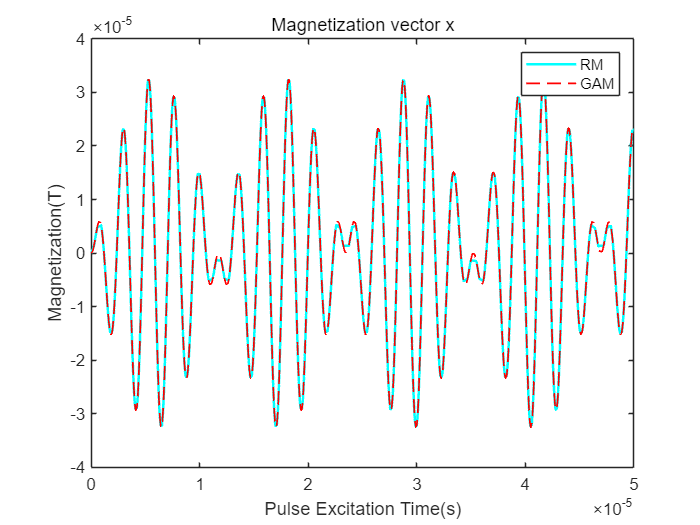

plot(T,M0_RM.rx,'c','LineWidth',1.5)
hold on
plot(T,M0_G.rx,'r--','LineWidth',1)
hold off
title('Magnetization vector x')
legend('RM','GAM')
xlim([0 T(end)])
xlabel('Pulse Excitation Time(s)');
ylabel('Magnetization(T)');
%%%%%%%%%%%%% y
figure
plot(T,M0_RM.ry,'c','LineWidth',1.5)

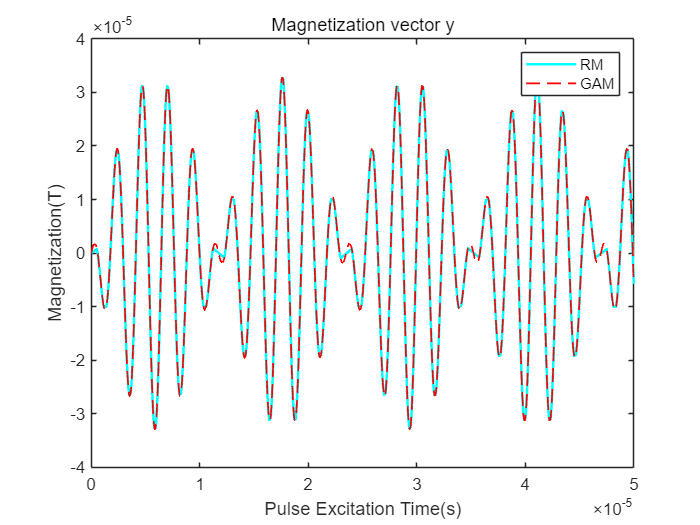

hold on
plot(T,M0_G.ry,'r--','LineWidth',1)
hold off
title('Magnetization vector y')
legend('RM','GAM')
xlim([0 T(end)])
xlabel('Pulse Excitation Time(s)');
ylabel('Magnetization(T)');
%%%%%%%%%%%%% z
figure
plot(T,M0_RM.rz,'c','LineWidth',1.5)

hold on
plot(T,M0_G.rz,'r--','LineWidth',1)
hold off
title('Magnetization vector z')
legend('RM','GAM')
xlim([0 T(end)])
xlabel('Pulse Excitation Time(s)');
ylabel('Magnetization(T)');

## 2. MAPE and Time Consumsing(Multiple Larmor Frequency and Single Time)

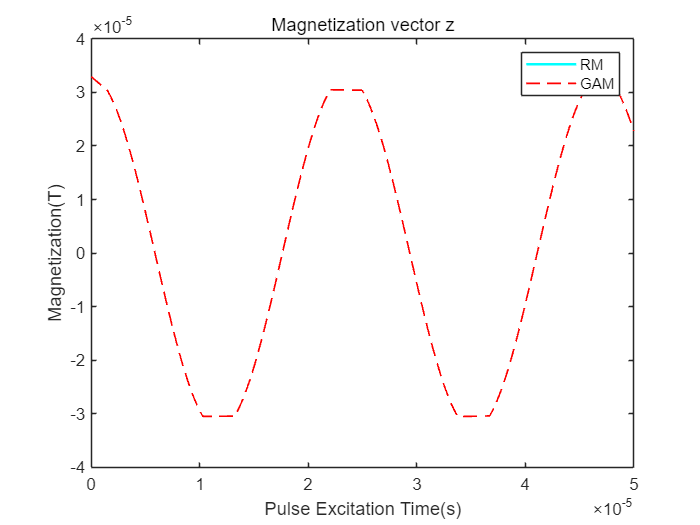

tdd = 2e-6;
gamma = 0.267518*1e9;        % Magnetic spin ratio
B0Hsum = 1e-2;

forwarding.TLoop.fT = gamma/2/pi*B0Hsum;
B1 = 1e-3;
%%%%%%%%% new
NM = round(logspace(5,9,10));
N     = 6.692*1e28;          % [/m^3]
hq    = 1.054571628*1e-34;   % Planck's constant/2*pi [J.s]
K     = 1.3805*1e-23;        % Boltzmann's constant  [J/K]
T0     = 293;                 % absolute temperature  [K]
for i = 1:length(NM)
    i
    %%%%%%%%%%%%%%%%%%%%%%%% inital
    nM = NM(i);
    alpha = linspace(-pi/3,pi/3,nM)';
    forwarding.alpha = alpha;
    forwarding.B0.Hsum = B1*tan(alpha) + B0Hsum;
    forwarding.B1Hsum = B1*ones(nM,1);
    M0stre = N * gamma^2 * hq^2 / (4 * K * T0) .* forwarding.B0.Hsum;  % magnetization vector strength
    randM0xyz = (rand(nM,3)-0.5)*2;
    M0_ini = randM0xyz./repmat(sqrt(sum(randM0xyz.^2,2)),1,3).*repmat(M0stre,1,3);
    %%%%%%%%%%%%%%%%%%%%%%%% method
    tic
    [M0_G] = IntegralM0_GM_V1(forwarding,M0_ini,tdd); %GAM
    t1(i) = toc;
    tic
    [M0_RM] = IntegralM0_RM_V1(forwarding,M0_ini,tdd); %RM
    t2(i) = toc;
    %%%%%%%%%%%%%%%%%% MAPE
    xxx = abs(M0_G.rx - M0_RM.rx)./abs(M0_RM.rx);
    yyy = abs(M0_G.ry - M0_RM.ry)./abs(M0_RM.ry);
    zzz = abs(M0_G.rz - M0_RM.rz)./abs(M0_RM.rz);
    xxx(isnan(xxx)) = 0;
    yyy(isnan(yyy)) = 0;
    zzz(isnan(zzz)) = 0;
    mape_x(i) = mean(xxx,'all');
    mape_y(i) = mean(yyy,'all');
    mape_z(i) = mean(zzz,'all');
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%  MAPE
figure
plot(NM,mape_x,'rd:','MarkerFaceColor','r')
hold on
plot(NM,mape_y,'gd:','MarkerFaceColor','g')

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

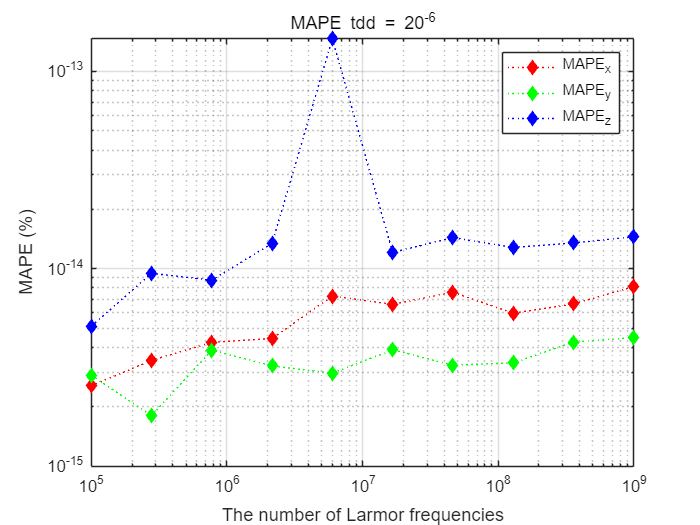

plot(NM,mape_z,'bd:','MarkerFaceColor','b')
hold off
title('MAPE tdd = 20^{-6}')
legend('MAPE_x','MAPE_y','MAPE_z')
ax5 = gca;
set(ax5,'YScale','log','XScale','log','XGrid','on','YGrid','on')
xlabel('The number of Larmor frequencies');
ylabel('MAPE (%)');
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%  Time consuming
figure
plot(NM,t2,'rd:','MarkerFaceColor','r')
hold on
plot(NM,t1,'b^--','MarkerFaceColor','r')

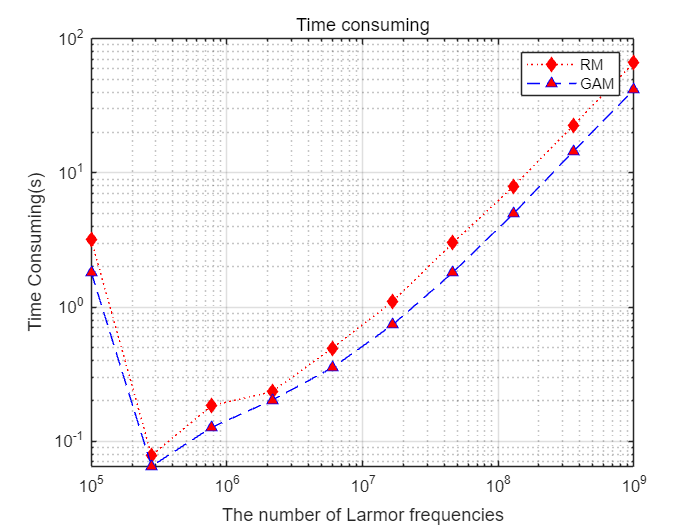

speed = -0.3165

hold off
title('Time consuming')
legend('RM','GAM')
ax3 = gca;
set(ax3,'YScale','log','XScale','log','XGrid','on','YGrid','on')
xlabel('The number of Larmor frequencies');
ylabel('Time Consuming(s)');
speed = mean((t1-t2)./t2)
% save('data.mat')